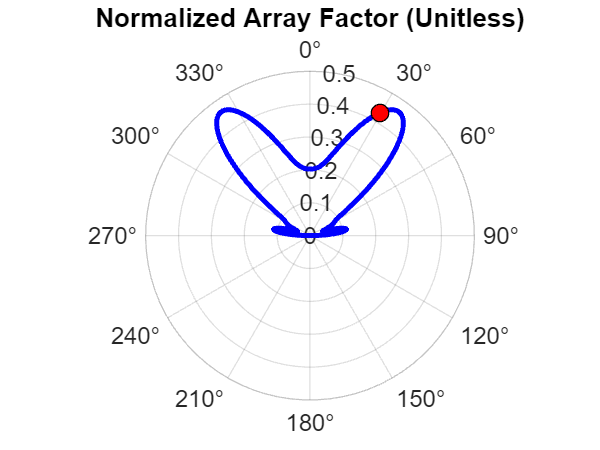


% Niranjan Mathirajan, Owen Davis
% November 8, 2025
% ECE 315H MATLAB Phased Array Antenna 
% Source 1: https://innovationspace.ansys.com/courses/wp-content/uploads/sites/5/2022/07/AntennaArrays_04ManipulatingtheArrayFactor.pdf
% Source 2: https://www.antenna-theory.com/arrays/arrayfactor.php
% Source 3: https://www.antenna-theory.com/definitions/wavevector.php

clc;
clf;

% -- constants --
f = 5e6; % frequency of antenna (Hz)
c = 3e8; % speed of light (m/s)
lambda = c/f; % wavelength (m)
k = 2 * pi/lambda; % 1-D wave vector, see source (3) (rad/m)


% -- array parameters --
N = 16; % number of antennas
nTheta = 180; 
theta = linspace(-pi/2, pi/2, nTheta); % range of angles the array "sees"
steerAngle = 0 * pi/180; % steering angle of array
dx_ideal = 0.25 * lambda; % expected distance between antennas
dx_error = 0.25 * lambda; % max variation in spacing
dx_actual = unifrnd(dx_ideal - dx_error, dx_ideal + dx_error, N); % compute random spacing
phase = -k * dx_ideal * cos(steerAngle); % term added to each AF to aim beam
measure_angle_deg = 30; % angle we measure AF at (range from 1 to 90)
measure_angle_rad = measure_angle_deg * 2*pi / 360;

% -- compute array factor -- 
AF = zeros(nTheta,1); 
for t = 1:nTheta
    for n = 1:N
        % AF equation from source (1):
        pos = sum(dx_actual(1:n-1)); % cumulative position
        AF(t) = AF(t) + exp(1j*k*pos*cos(theta(t)) + 1j*(n-1)*phase); 
    end
    AF(t) = AF(t)/N; % normalize AF, so max gain is 0dB
end

%{
Ey = 0*(1:N);
for n = 1:N
    if n == 1
        Ey(n) = 1;
    else
    pos_mean = (n-1)*dx_ideal;
    B = j*(n-1)*k*cos(measure_angle_rad);
    Ey(n) = (exp(B*(dx_ideal + dx_error)) - exp(B*(dx_ideal - dx_error))) / (B*2*dx_error);
    end
end
disp(sum(abs(Ey))/N)
%}


% -- plotting --
hps = polaraxes;
polarplot(theta, abs(AF),"blue", 'LineWidth',2); % plot AF
hold on;
% place dot on AF at our measure angle
polarplot(measure_angle_rad, abs(AF(measure_angle_deg + 90)), 'o', 'MarkerSize', 7, 'MarkerFaceColor', 'r', 'MarkerEdgeColor','black');
hps.ThetaZeroLocation = 'top'; % make 0 degrees show up at top of plot
ax = gca;
hps.ThetaDir = 'clockwise';
gca.FontSize = 12;
title('Normalized Array Factor (Unitless)');
grid on;